clear;clc;close all;

A=[1 3;2 0.5]

A =     1.0000    3.0000
    2.0000    0.5000


[V,D]=eig(A)

V =     0.8048   -0.7418
    0.5935    0.6706


D =     3.2122         0
         0   -1.7122



figure;
hold on;grid on;axis equal;set(gca,'fontname','メイリオ');
th=linspace(0,2*pi,100);
plot(cos(th),sin(th),'g--');
if abs(D(1,1))>abs(D(2,2))
    plot([0 V(1,1)],[0,V(2,1)],'bo-','LineWidth',3);
    plot([0 V(1,2)],[0,V(2,2)],'bo-');
else
    plot([0 V(1,1)],[0,V(2,1)],'bo-');
    plot([0 V(1,2)],[0,V(2,2)],'bo-','LineWidth',3);
end

x=[1;0];

plot([0 x(1)],[0,x(2)],'r:*');
text(x(1),x(2),[num2str(0)],'fontname','メイリオ');
for n1=1:10
    x=A*x;
    plot([0 x(1)],[0,x(2)],'r:*');
    text(x(1),x(2),[num2str(n1)],'fontname','メイリオ');
    x=x/norm(x)
    plot([0 x(1)],[0,x(2)],'r--s');
end

x =     0.4472
    0.8944


x =     0.9191
    0.3939


x =     0.7182
    0.6958


x =     0.8438
    0.5367


x =     0.7820
    0.6233


x =     0.8164
    0.5774


x =     0.7985
    0.6020


x =     0.8082
    0.5889


x =     0.8030
    0.5959


x =     0.8058
    0.5922


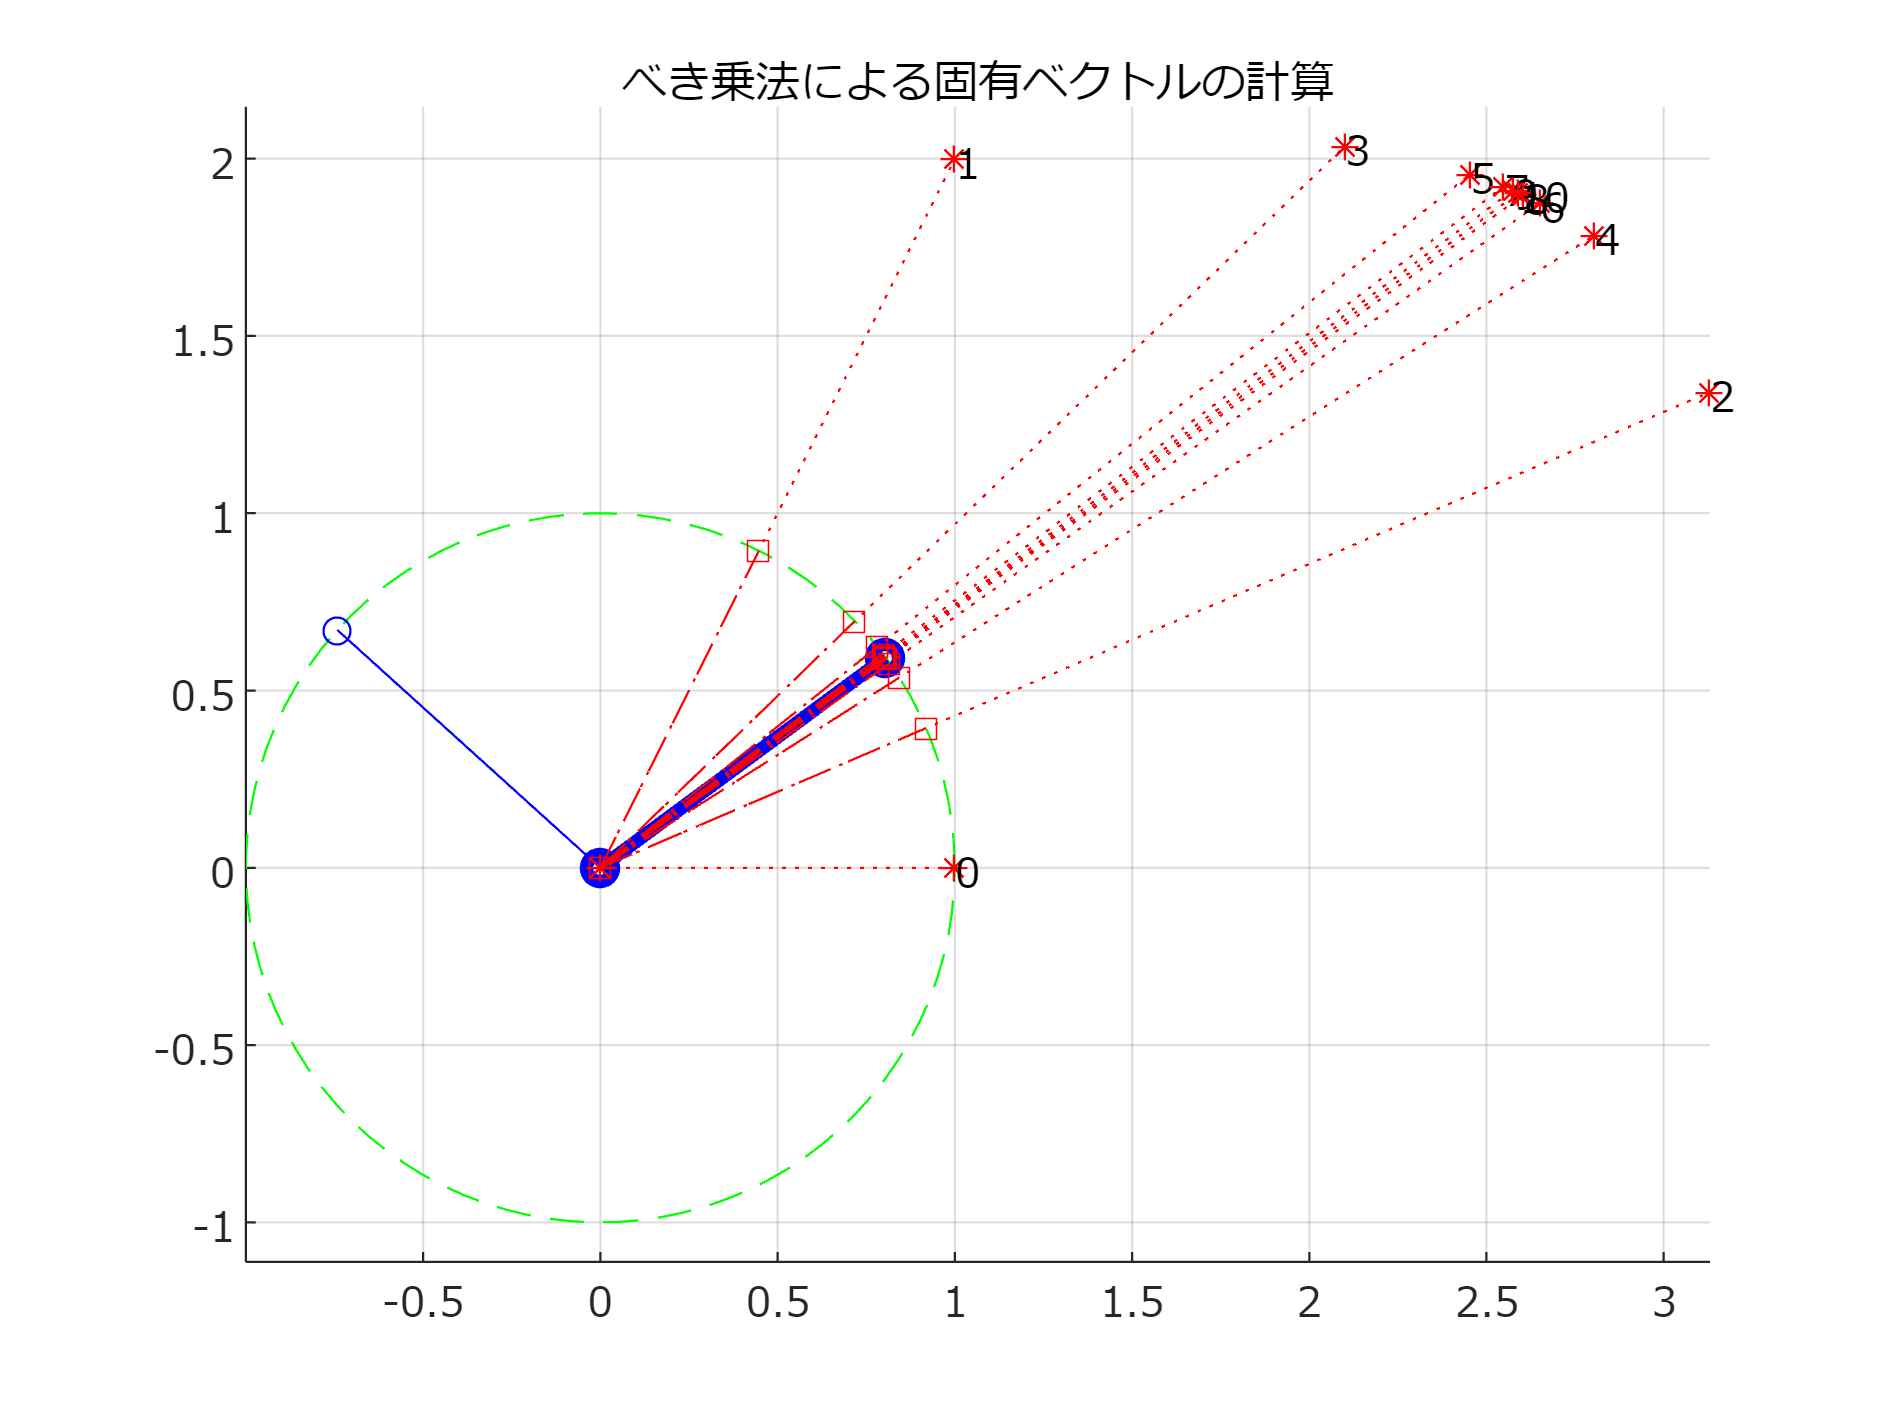

title('べき乗法による固有ベクトルの計算');
exportgraphics(gcf,'fig_Exercise_ChapA_eigVec.pdf')